%{
cd /Users/joyce/Github/isetcam;
addpath(genpath(pwd));
cd /Users/joyce/Github/isetfluorescence;
addpath(genpath(pwd));
cd /Users/joyce/Github/oraleye/;
addpath(genpath(pwd));
cd /Users/joyce/Github/oe_tongue_lip/;
addpath(genpath(pwd));
%}

ieInit;
wave = 500:595;
normWave = 520;
% fise_plotDefaults;
 

## Read the saved model fluorophores

These have no blood.  The blood will be read in during the fitting process with oeSolveBlood.

fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
[savedFluorophores,~,comment] = ieReadSpectra(fname,wave);
%{
plotRadiance(wave,savedFluorophores);
legend(comment.names);
%}

## Read the external data


BuccalMucosaBetz  = ieReadSpectra('BuccalMucosaBetz1999.mat',wave); 
BuccalMucosaBetz  = BuccalMucosaBetz /BuccalMucosaBetz(wave == 520);

HardPalateBetz  = ieReadSpectra('HardPalateBetz1999.mat',wave); 
HardPalateBetz  = HardPalateBetz /HardPalateBetz(wave == 520);

InnerLipBetz = ieReadSpectra('InnerLipBetz1999.mat',wave);
InnerLipBetz  = InnerLipBetz  /InnerLipBetz(wave == 520);

TongueBetz = ieReadSpectra('TongueBetz1999.mat',wave);
TongueBetz  = TongueBetz /TongueBetz(wave == 520);

ieFigure; plot(wave,BuccalMucosaBetz); hold on;
plot(wave,HardPalateBetz);
plot(wave,InnerLipBetz);
plot(wave,TongueBetz);
title('Data from Betz 1999');
legend('Buccal Mucosa', 'Hard Palate', 'Inner Lip', 'Tongue');


## Fit the model to tongue data

[odT,weightsT,finalFluorophoresT] = oeSolveBlood(wave,TongueBetz,savedFluorophores);
%{
plotRadiance(wave,finalFluorophoresT);
legend(comment.names);
%}
predictedT = finalFluorophoresT*weightsT(:);
ieFigure;
plot(wave,predictedT,'k--',wave,TongueBetz);
grid on;
title(sprintf('Tongue Betz (od = %.3f)',odT));
legend("predicted","Tongue Betz");

## Fit the model to the inner lip data

only use collagen and FAD - no keratin in inner lip

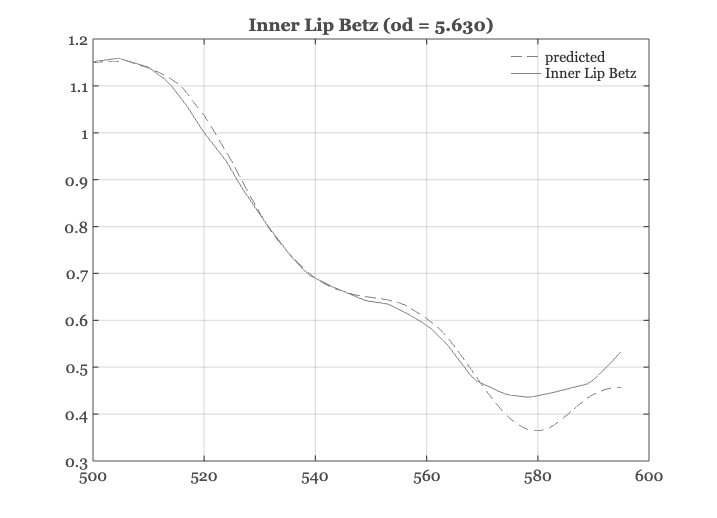

[odL,weightsL,finalFluorophoresL] = oeSolveBlood(wave,InnerLipBetz,savedFluorophores(:,1:2));
predictedL = finalFluorophoresL*weightsL(:);
ieFigure;
plot(wave,predictedL,'k--',wave,InnerLipBetz,'Color',[1 1 1]*0.5);
grid on;
legend({'predicted','Inner Lip Betz'});
title(sprintf('Inner Lip Betz (od = %.3f)',odL));

## Fit the model to the Hard Palate data

[odH,weightsH,finalFluorophoresH] = oeSolveBlood(wave,HardPalateBetz,savedFluorophores);
predictedH = finalFluorophoresH*weightsH(:);
ieFigure;
plot(wave,predictedH,'k--',wave,HardPalateBetz);
grid on;
title(sprintf('Hard PalateBetz (od = %.3f)',odT));
legend("predicted","Hard PalateBetz")

## Fit the model to the Buccal Mucosa data 

[odB,weightsB,finalFluorophoresB] = oeSolveBlood(wave,BuccalMucosaBetz,savedFluorophores);
predictedB = finalFluorophoresB*weightsB(:);
ieFigure;
plot(wave,predictedB,'k--',wave,BuccalMucosaBetz);
grid on;
title(sprintf('Buccal MucosaBetz (od = %.3f)',odT));
legend("predicted","Buccal MucosaBetz")